%% compressive sensing

% compressive sensing functions by reconstructing
% signals/images by leveraging a sparsity assumption which
% is true for our simplified point scatterer case. I am
% going to start by reproducing the compressive sensing
% implementation I used for a signal, then I will scale to a
% two-dimensional image
rng(0)

% initialize the length of the signal and the number of
% non-zero points
N = 100; nz = 3; 

% number of measurements and std deviation of error
m = 30; sigma = 0.01;

non_zero_idx = randi([2, N/2], nz, 1);
mag = randi([3,5], nz, 1);
phase = exp(1j * 2 * pi * rand(nz,1));
coeff = mag .* phase;

X = zeros(N,1);
X(non_zero_idx) = coeff;

for k = non_zero_idx
    if k == N/2 + 1
        continue
    end
    mirror = N - k + 2;
    X(mirror) = conj(X(k));
end


fprintf('Non-zeros indices at: %i, %i and %i', non_zero_idx)

Non-zeros indices at: 41, 46 and 8

% formulate the measured signal y = Ax + n where A is the
% system or sensing matrix, y is the measurement, x is the
% signal and n is the noise

F = (1/sqrt(N)) * fft(eye(N));
Psi = conj(F);

x = real(Psi * X);

Phi = rand(m,N) / sqrt(m);

A = Phi * Psi;

% calculate the measurement
y = A * X + sigma * randn(m, 1);

f=figure;
subplot(1,2,1)
stem(-N/2:N/2-1, fftshift(abs(X)), 'LineWidth',2)
title('Truth signal','FontSize',24)
xlabel('frequency (Hz)','FontSize',16)
ylabel('magnitude','FontSize',16)

subplot(1,2,2)
stem(x, 'LineWidth',2)
title('Truth signal','FontSize',24)
xlabel('time (s)','FontSize',16)
ylabel('magnitude','FontSize',16)
set(gcf, 'Position', get(0, 'Screensize'));
saveas(f,'plots/truth_fft.png')

figure
stem(y, 'LineWidth',2)

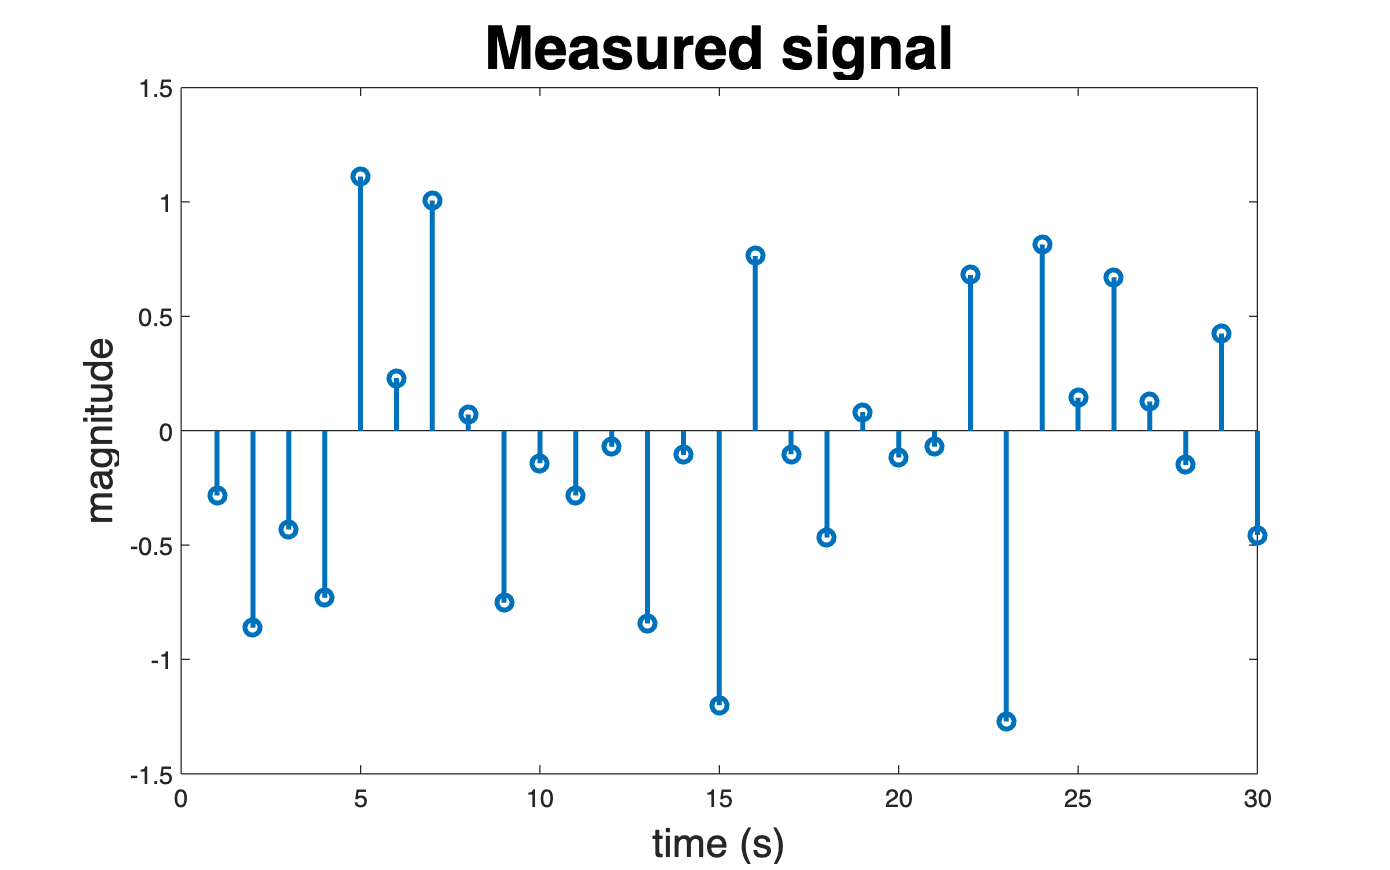

title('Measured signal','FontSize',24)
xlabel('time (s)','FontSize',16)
ylabel('magnitude','FontSize',16)
set(gcf, 'Position', get(0, 'Screensize'));

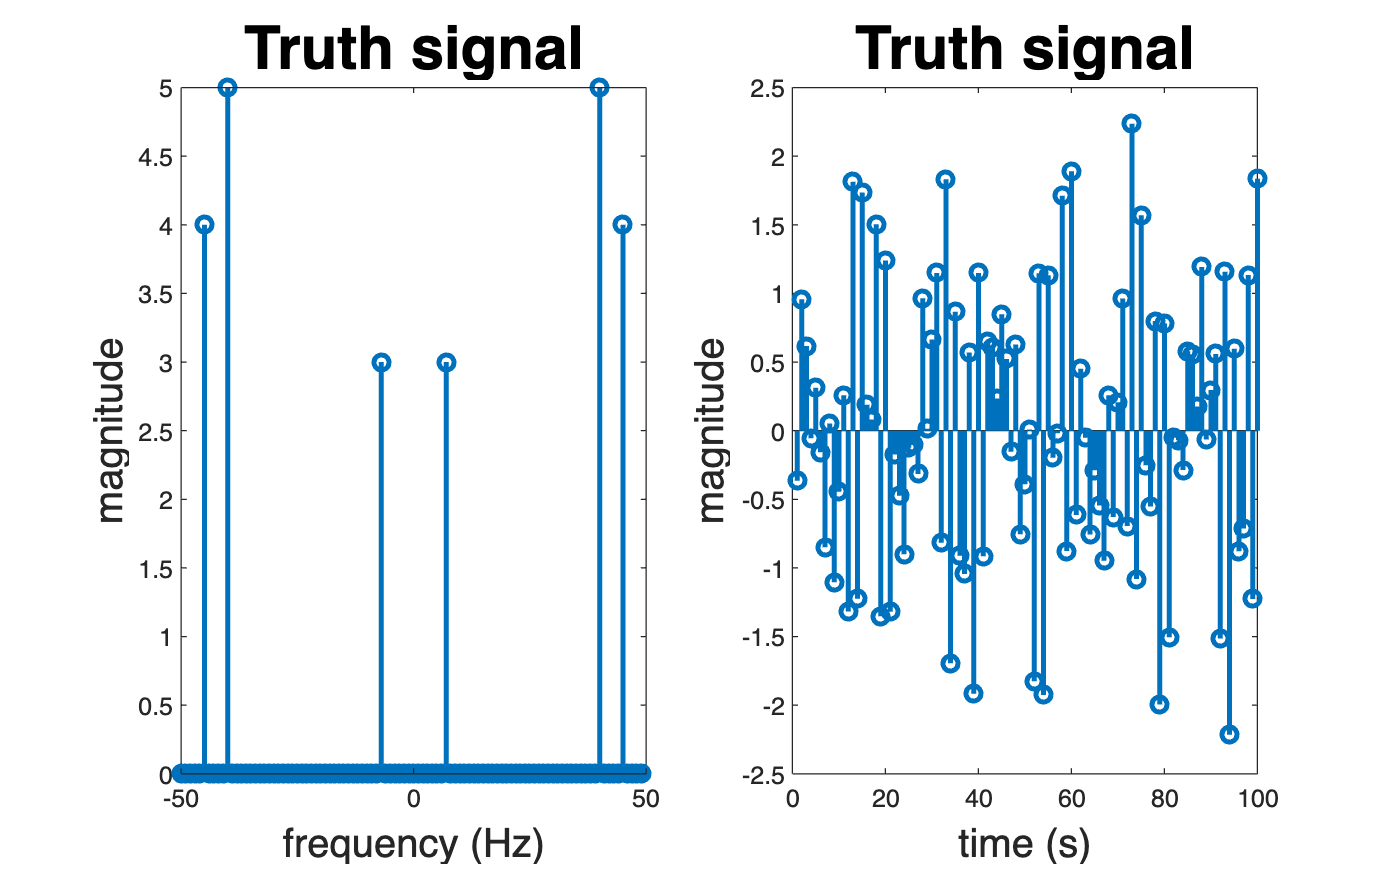

saveas(f,'plots/meas_fft.png')

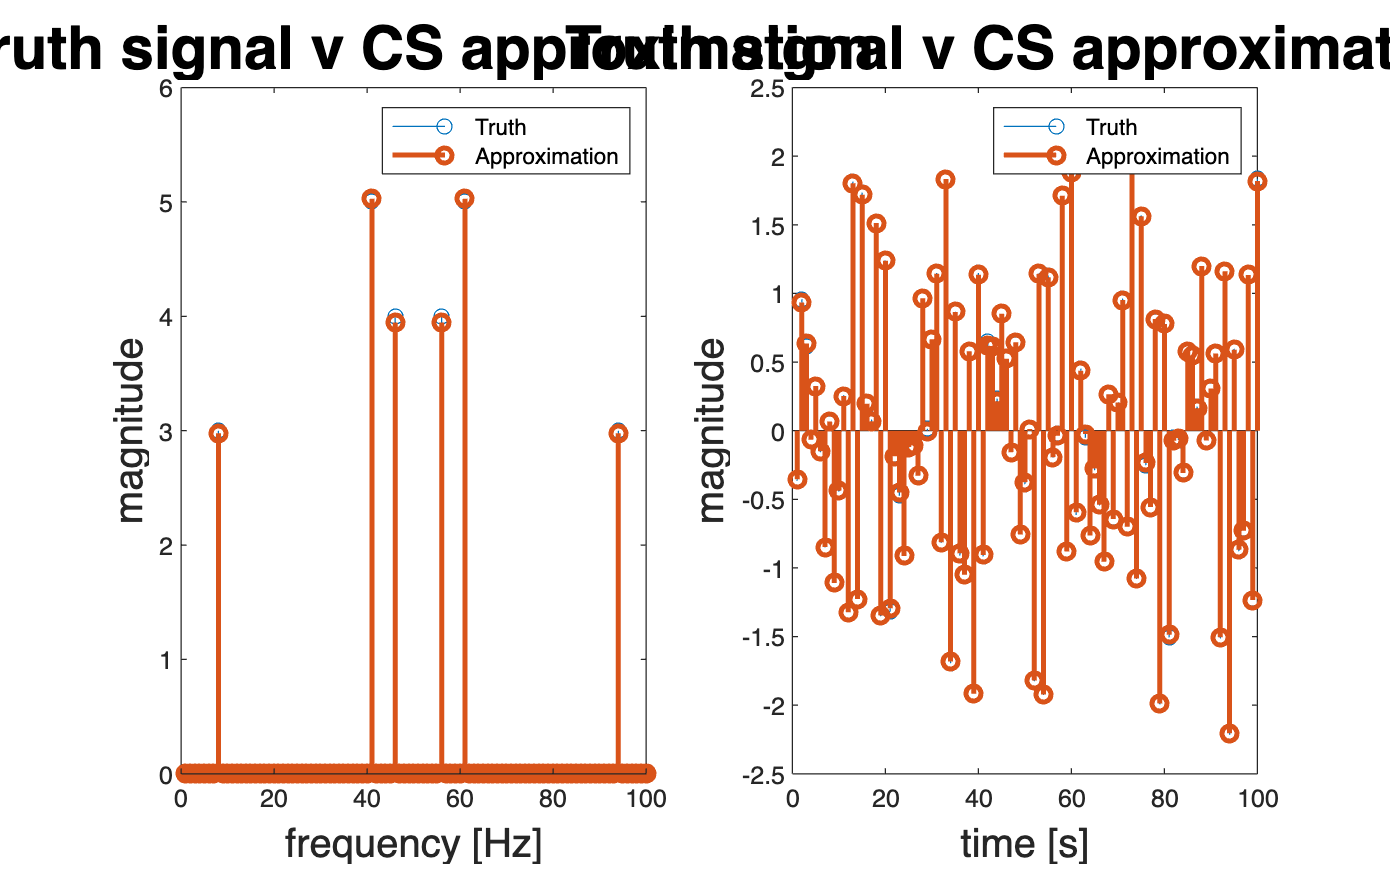

% Apply compressive sensing techniques using the orthogonal
% matching pursuit method which assumes the columns of A
% (iid Gaussian) are roughly orthogonal. The goal is to
% determine the basis vector in A that is overlaps the most
% with the measurement. This overlap is determined by an
% inner product between the measurement and each vector,
% resulting in the transformation coefficients. The greater
% the magnitude of the coefficient, the greater the overlap.
% Select the basis vector in A with the greatest inner
% product, and solve for an approximation of signal by
% minimizing || y - Ax ||_{2}^{2} using the least squares method 

% initialize the array containing the approximate non-zero
% indices
Lambda = []; X_hat = zeros(N,1);

% for now, assume we have knowledge of the number of
% nonzeros
r = y;
for i = 1:nz*2+1

    % inner product of the measurement and basis vectors
    c = A'* r;

    % find the index that maximizes the inner product
    [~, l] = max(abs(c));
    Lambda = [Lambda; l];

    % use this basis vector to calculate the least squares
    % solution
    X_hat(Lambda) = inv(A(:,Lambda)'*A(:,Lambda))*A(:,Lambda)'*y;
    r = y - A * X_hat;
end

x_hat = real(Psi * X_hat);

f = figure;
subplot(1,2,1)
stem(1:size(X,1),abs(X), 'DisplayName', 'Truth')
hold on
stem(1:size(X_hat,1),abs(X_hat),'DisplayName','Approximation', 'LineWidth',2)
title('Truth signal v CS approximation','FontSize',24)
xlabel('frequency [Hz]','FontSize',16)
ylabel('magnitude','FontSize',16)
legend

subplot(1,2,2)
stem(1:size(x,1),x, 'DisplayName', 'Truth')
hold on
stem(1:size(x_hat,1),x_hat,'DisplayName','Approximation','LineWidth',2)
title('Truth signal v CS approximation','FontSize',24)
xlabel('time [s]','FontSize',16)
ylabel('magnitude','FontSize',16)
legend
set(gcf, 'Position', get(0, 'Screensize'));
saveas(f,'plots/recon_fft.png')